## Import data and Sample Selection

import data from ../data/sdss_merge.dat

DataFileFolder = '../data/';
OriData = importdata([DataFileFolder,'sdss_merge.dat']);

OriData is the 14301*21 array.

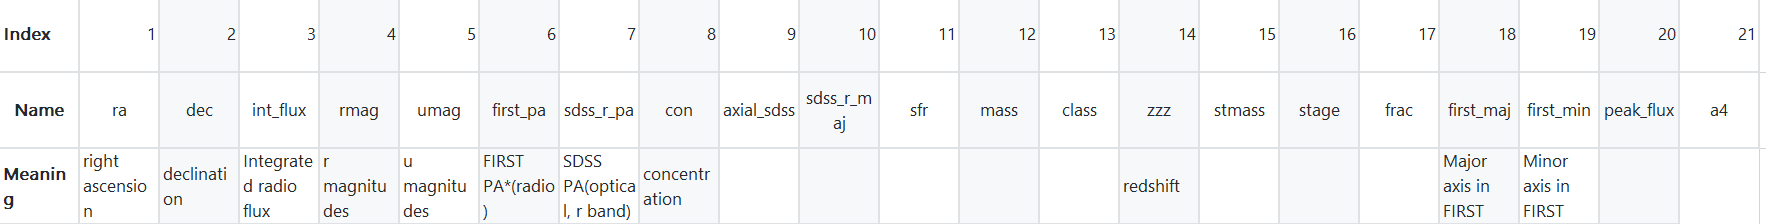

*Exclude galaxies with r>18, b/a>0.8 in either SDSS or FIRST and a<2 arcsec in FIRST. (Actually this should have done with data because the number of lines, 14301, is the same with total 14302 galaxies performed in the paper. I just double-check it)*

SelData = OriData(OriData(:,4) <=18 ...
    & OriData(:,19)./OriData(:,18)<=0.8 ...
    & OriData(:,18)>=2 ,:);

We use r-band PA as suggested.

## Section 3.1

### Figure 1 Comparison of the PA measured in different bands. 

Only PA in r band are available 

*The histograms are of the percentage of galaxies in each of the bins. The solid line represents the comparison between r and g, the dotted line that between g and i and the dashed line between i and r. *

### Figure 2. The percentage of galaxies against the PA difference measured in the r and u bands.

*The solid line has 0.6 < b/a < 0.8, dotted line 0.4 < b/a < 0.6 and dashed line b/a < 0.4. The equivalent histogram for all values of the axial ratio is the dashed line in Fig. 1*

### Figure 3. Histograms of $\Delta \alpha$ (bottom panel), $\alpha_{\textrm{SDSS}}$ and $\alpha_{\textrm{FIRST}}$ using 18 bins for all 14,302 galaxies.

*Included also are the Poisson errors for each bin. *$\Delta \alpha$* is defined to be the acute angle between the two PA *$\alpha_{\textrm{SDSS}}$* and *$\alpha_{\textrm{FIRST}}$*.*

DeltaAlpha = abs(SelData(:,6)-SelData(:,7));

DeltaAlpha(DeltaAlpha>90) = 180 - DeltaAlpha(DeltaAlpha>90);
SelData(SelData(:,7)> 90,7) =  SelData(SelData(:,7)> 90,7) - 180;
SelData(SelData(:,6)>90,6) = SelData(SelData(:,6)>90,6) -180;

Con = SelData(:,8);
rMag = SelData(:,4);
uMag = SelData(:,5);
baxis = SelData(:,19);
aaxis = SelData(:,18);
paSDSS = SelData(:,7) ;
paFIRST = SelData(:,6);

missing the error of PA?

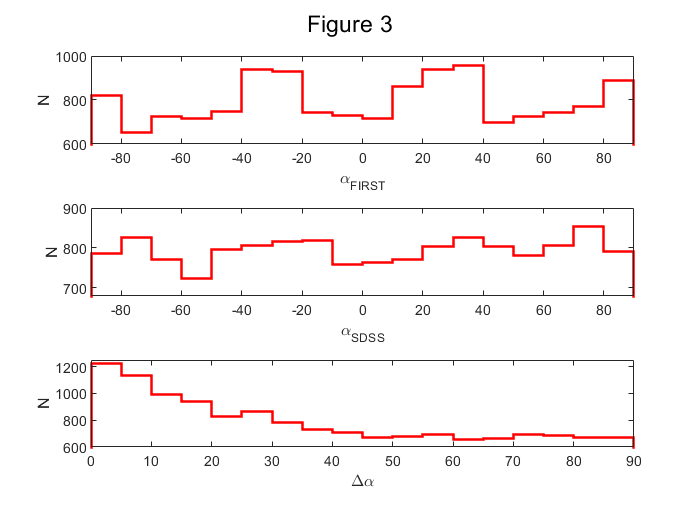


bins = 18;
Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

subplot 311
% FIRST PA
histogram(paFIRST,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
ylim([600,1000])
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{FIRST}')
subplot 312
histogram(paSDSS,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
ylim([680,900])
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{SDSS}')
subplot 313
h= histogram(DeltaAlpha,Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
ylim([600,1250])
ylabel('N')
xlim([0 90])
xlabel('\Delta\alpha')
sgtitle('Figure 3')

### Figure 4. Equivalent to Fig. 3 but for six bins.

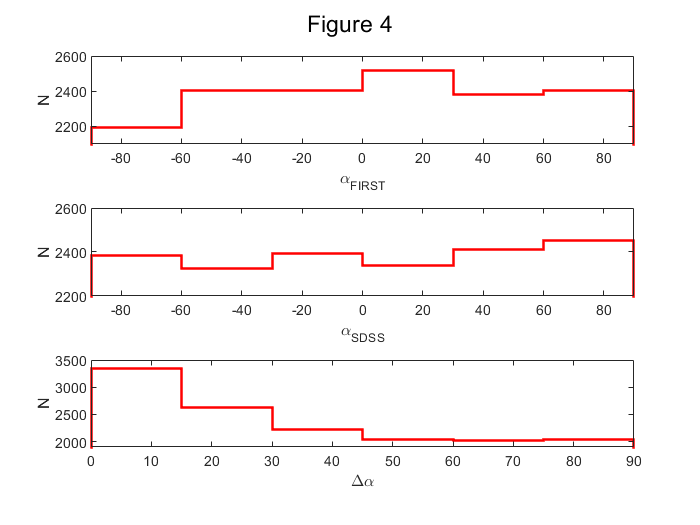

bins = 6;
Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

subplot 311

% FIRST PA

histogram(paFIRST,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
ylim([2100 2600])
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{FIRST}')

subplot 312
histogram(paSDSS,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
ylim([2200 2600])
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{SDSS}')
subplot 313
h= histogram(DeltaAlpha,Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
ylim([1900 3500])
ylabel('N')
xlim([0 90])
xlabel('\Delta\alpha')
sgtitle('Figure 4')

### Subtle systematic effects

We have selected a subset of FIRST sourc*es to have a completely flat distribution of PA and also divided the original sample into different areas and looked for different systematics in different areas of sky. We still see similar biases to those in Fig. 3 in the PA differences in the sample in which the FIRST PA distribution is flat. In the second test, we find that the FIRST PA distribution is roughly the same independent of where we look in the sky.*

At first, plot the location of the selected radio sources.

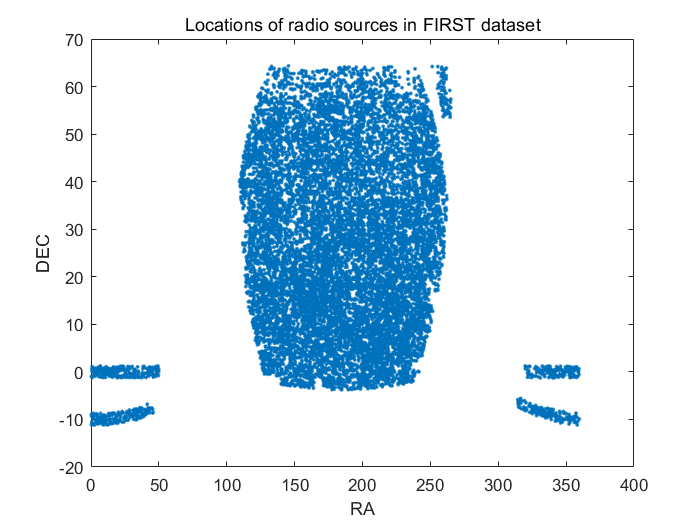

figure

plot(SelData(:,1),SelData(:,2),'.');xlabel('RA');ylabel('DEC')
title('Locations of radio sources in FIRST dataset')

Then we divided them into different areas and plot the histogram of FIRST PA in those area part

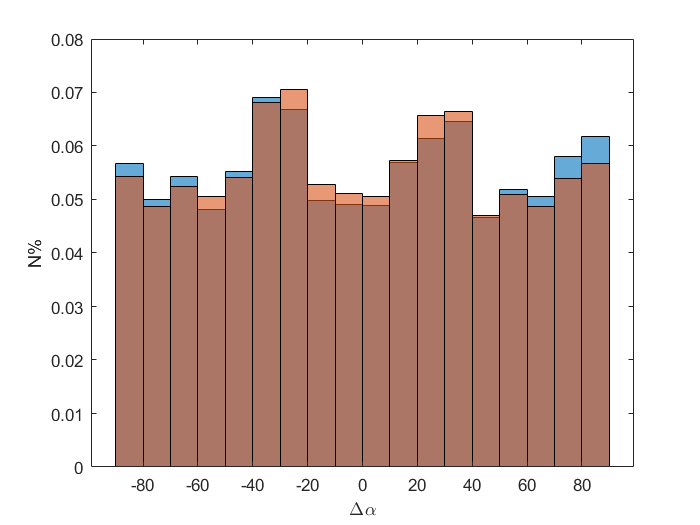

i=0;
figure
hold off
while(i<2)
    % selected a random area
    RaRand = randi([110 250],2,1);
    DecRand = randi([0 65],2,1);
    AreaData = SelData( ...
        SelData(:,1)>=min(RaRand) ...
        &SelData(:,1)<=max(RaRand) ...
        &SelData(:,2)>=min(DecRand) ...
        &SelData(:,2)<=max(DecRand),:);
    % remove some area which is too small for analysis.
    if(length(AreaData(:,6))<5000)
        continue
    end
    histogram(AreaData(:,6),18 ,'Normalization','probability');i=i+1;
    hold on
end
xlabel('\Delta\alpha')
ylabel('N%')

From this figure, the FIRST PA distribution is independent of the area selected in the sky.

## Section 3.2

### Figure 5. Split of the sample by colour and concentration. 

*For colour, we split u − r < 3 (left-hand plots) and u − r > 3 (right-hand plots), and for concentration we use c < 3 (left-hand plots) and c > 3 (right-hand plots). The two right-hand plots are peaked at*$\Delta \alpha =0^◦$*, whereas the two left-hand plots are biased towards  *$\Delta \alpha ={90}^◦$

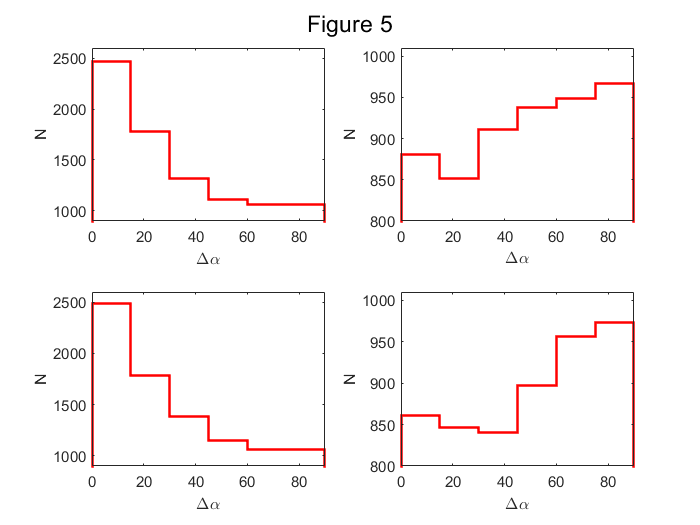

Edge90 = linspace(0,90,7);
for RowIndex = 0:1
for ColIndex = 1:2

if(RowIndex==1)
aaa = SelData(:,5)-SelData(:,4);
else
aaa = SelData(:,8);
end

if(ColIndex==1)
SelectedRow = aaa<3;
yLimintarray = [900 2600];
else
SelectedRow = aaa>=3;
yLimintarray = [800 1010];
end

subplot(2,2,RowIndex*2 + ColIndex)
histogram(DeltaAlpha(SelectedRow),Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
ylim(yLimintarray)
xlim([0 90])
xlabel('\Delta\alpha')
ylabel('N')
end
end
sgtitle('Figure 5')

#### Figure 6. Scatter plot of the colour u − r versus c 

*Scatter plot of the colour u − r versus c for the whole sample of 14 302 galaxies. Included also are the lines C1 = 2.0 (dashed line) and C2 = 3.5 (solid line).*

figure
plot(SelData(:,5)-SelData(:,4),SelData(:,8),'.r','MarkerSize',0.5);
hold on

Draw the line where C1 = 2.0 and C2 =3.5

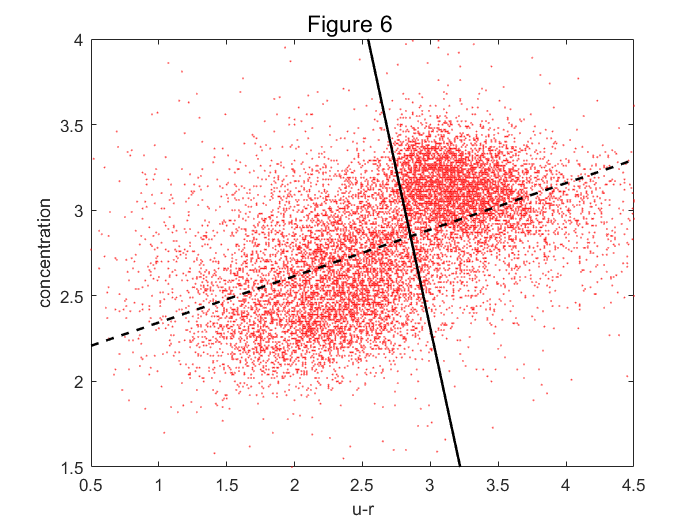

X = linspace(0.5,4.5,1000);
C1 = 2;C2 = 3.5;
Y = (C2 - 0.965.*X)./0.262;
plot(X,Y,'-k','LineWidth',1.5);

Y = (C1 + 0.262.*X)./0.965;
plot(X,Y,'--k','LineWidth',1.5)

ylim([1.5 4])
xlim([0.5 4.5])
xlabel('u-r')
ylabel('concentration')
sgtitle('Figure 6')

#### Figure 7. Various splits of the data determined on the basis of the PCA analysis and the axial ratio

*(bottom-left panel) C2 < 3.5; (bottom-right panel) C2 > 3.5; (top-left panel) C2 > 3.5 and b/a < 0.6; (top-right panel) C2 > 3.5 and b/a > 0.6*

Top panel

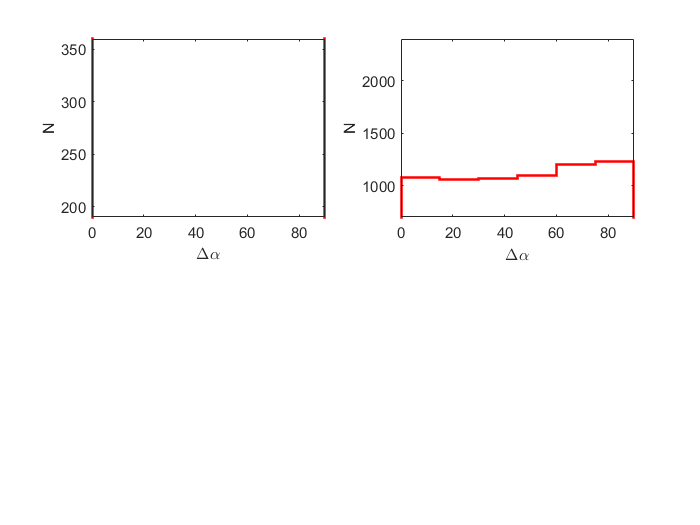

figure
Edge90 = linspace(0,90,7);

for ColIndex = 1:2

aaa = C2function(Con,uMag,rMag);

if(ColIndex==1)
SelectedRow = aaa<3.5;
yLimintarray = [190 360];
else
SelectedRow = aaa>=3.5;
yLimintarray = [700 2400];
end

subplot(2,2, ColIndex)
histogram(DeltaAlpha(SelectedRow),Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
ylim(yLimintarray)
xlim([0 90])
xlabel('\Delta\alpha')
ylabel('N')
end

Bottom panel

for ColIndex = 1:2

C2 = C2function(Con,uMag,rMag);

if(ColIndex==1)
SelectedRow = C2>=3.5 & baxis./aaxis ;
yLimintarray = [190 360];
else
% SelectedRow = C2>=3.5 & ;
yLimintarray = [700 2400];
end

subplot(2,2, ColIndex)
histogram(DeltaAlpha(SelectedRow),Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
ylim(yLimintarray)
xlim([0 90])
xlabel('\Delta\alpha')
ylabel('N')
end

sgtitle('Figure 7')

function c1 = C1function(c,u,r)
c1 = 0.965.*c - 0.262.*(u-r);
end
function c2 = C2function(c,u,r)
% C2function(c,u,r)
c2 = 0.262.*c + 0.965.*(u-r);
end